## A minimalistic Echo State Networks demo with Mackey-Glass (delay 17) data in "plain" scientific Python 

### by Mantas Lukoševičius 2012. Original Source: [http://minds.jacobs-university.de/mantas](http://minds.jacobs-university.de/mantas)

## Modified and adapted for Sine Wave Synthesis using a Small-World Architecture 

### by Jack Kenney 2018, translated and optimized in MATLAB 2019. BINDS Lab, CICS, UMass Amherst

% data parameters
hyper.in_size = 2;             % input vector size
hyper.out_size = 1;            % output vector size
% hyper parameters
hyper.res_size = 350;          % size of reservoir
hyper.leak = 0.15;             % leaking rate for integrator neurons
hyper.noise_mag = 1e-9;        % magintude of noise term
hyper.reg = 1e-8;              % regularization constant
hyper.aux = 1;                 % a_0 for x^0 doing a linear fit, bias term
hyper.feedback_scaling = 1.5;  % output feedback scaling
hyper.train_test_ratio = 0.8;
hyper.init_ratio = 0.1; 
hyper.beta = 0.7;
hyper.K = 4;

load('data/waves_20_100')
% normalize to prevent neuron saturation
input_data = normalize(input_data,2);

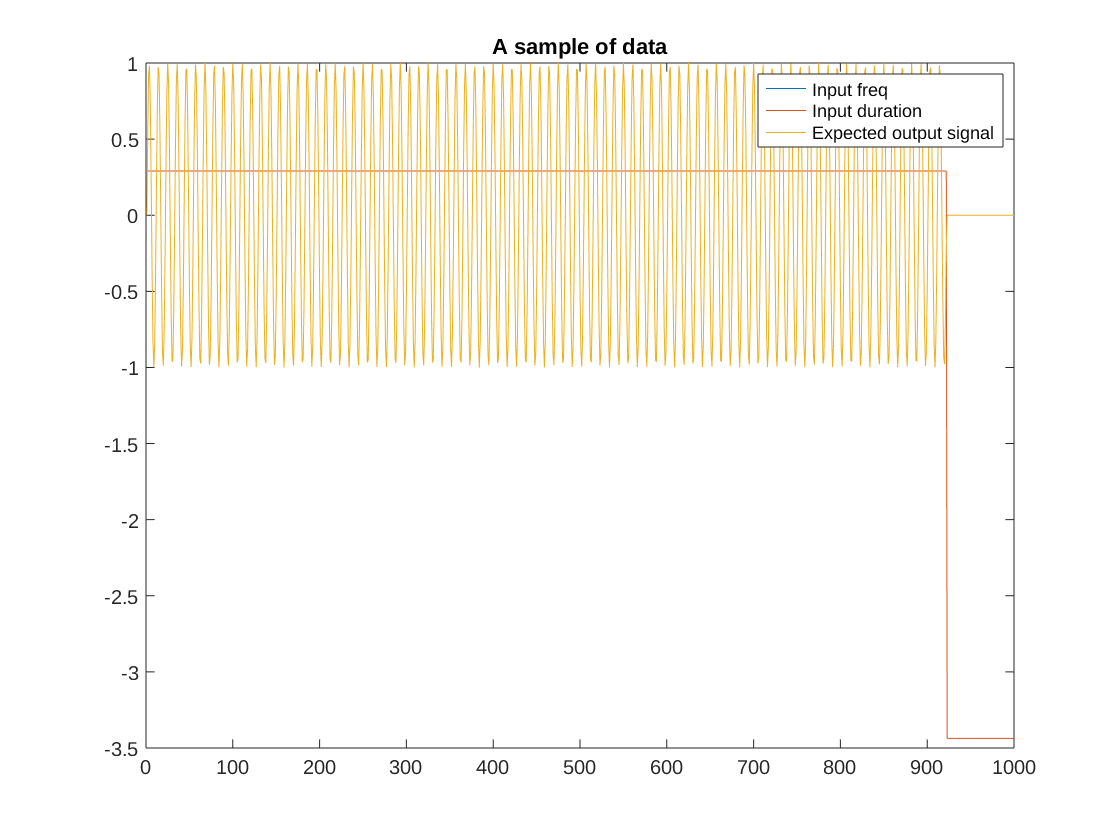

% plot some of the data
figure(1)
plot(input_data(1,:,1))
hold on
plot(input_data(1,:,2))
plot(output_data(1,:))
title('A sample of data')
legend('Input freq', 'Input duration', 'Expected output signal')

rng(42)

disp('Building small world...');

Building small world...


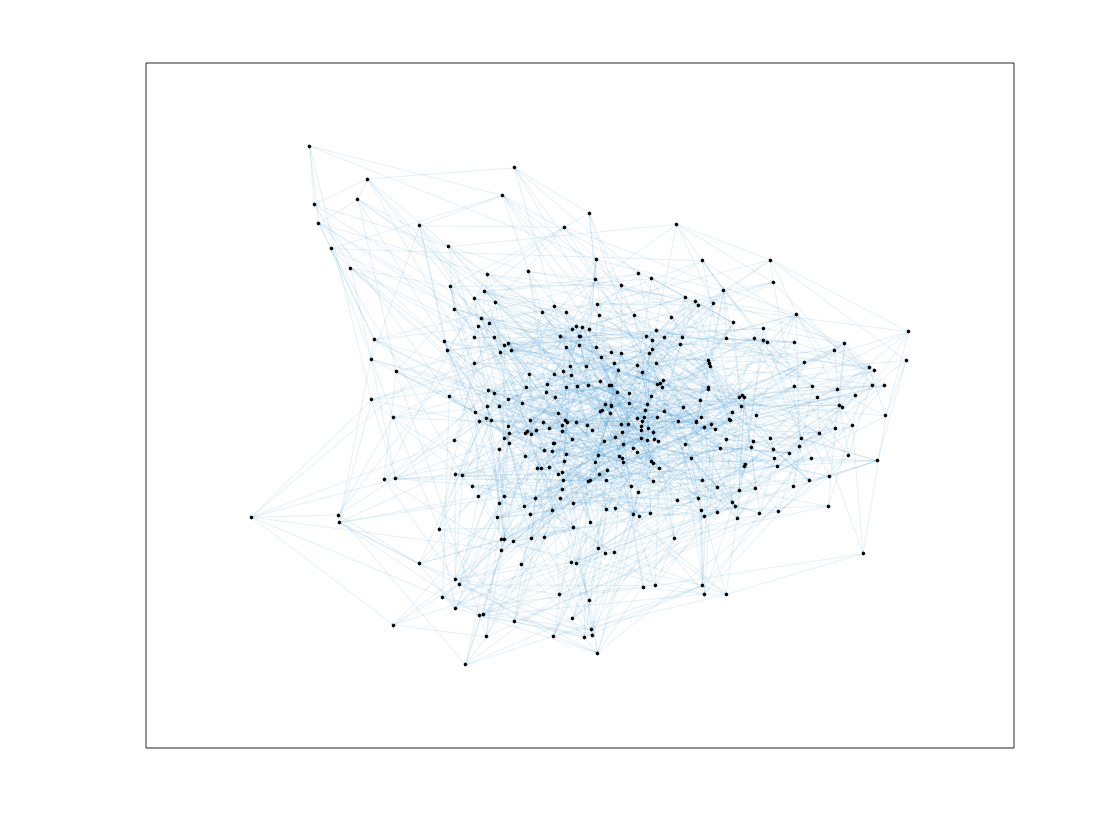

G = WattsStrogatz(hyper.res_size, hyper.K, hyper.beta);
figure(2)
plot(G,'NodeColor','k','EdgeAlpha',0.1);

Win = rand([hyper.res_size, 1 + hyper.in_size]) * 2 - 1;
W = adjacency(G);
for i = 1:size(W,1)
    parfor j = 1:size(W,2)
        % assign rand to edge (each edge is init_len to 1)
        W(i,j) = W(i,j) * (rand()*2-1);
    end
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).



% initialize random weight matrices
Wfb = rand([hyper.res_size, hyper.out_size]) * 2 - 1;
disp('done.')

done.


% add to struct
weights.Win = Win;
weights.W = W;
weights.Wfb = Wfb;

disp('Printing graph...')

Printing graph...


savefig("last_internal_weight_graph")
disp('done.')

done.


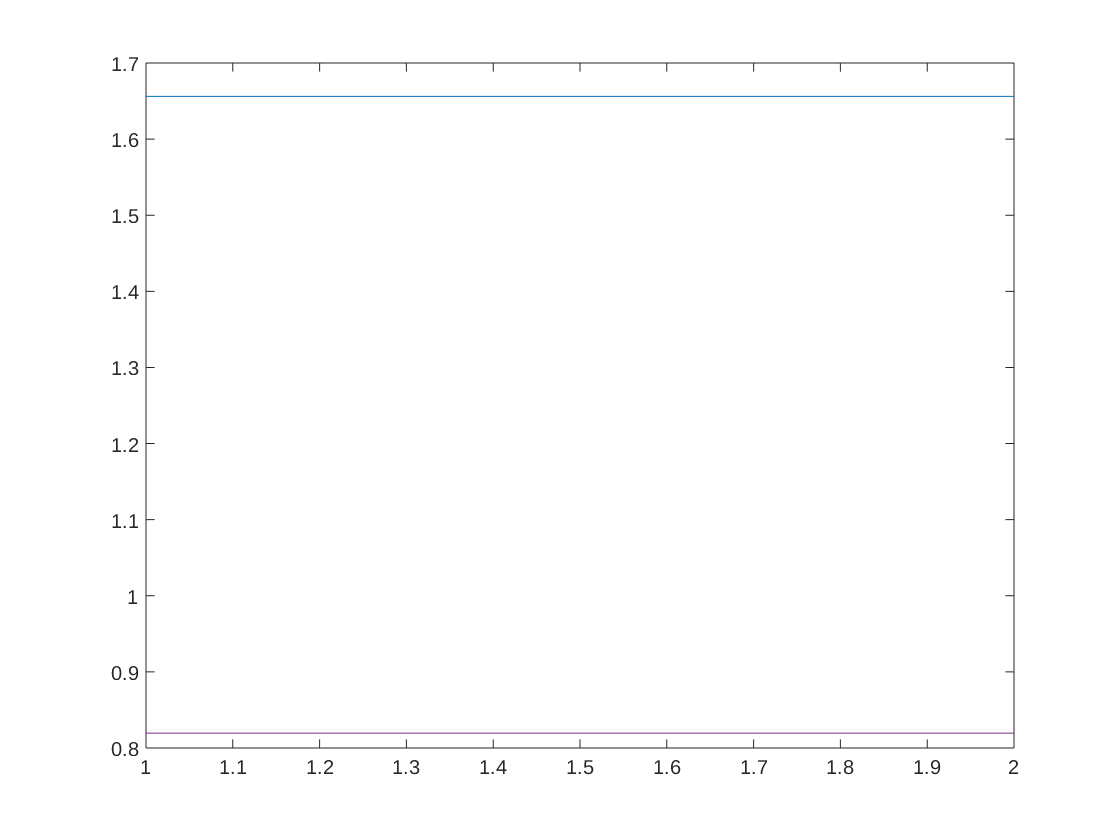

% DIVIDE DATA
[in_init, in_train, in_test] = divide_data(input_data,sample_lengths,hyper,hyper.in_size);
[out_init, out_train, out_test] = divide_data(output_data,sample_lengths,hyper,hyper.out_size);

% TRAIN
disp('Beginning training...');

Beginning training...


% allocated memory for the design (collected states) matrix
X = zeros([1+hyper.in_size+hyper.res_size, size(in_train,1)]);
% set the corresponding target matrix directly
Yt = output_data(size(in_init,1)+1:size(in_train,1));
% run the reservoir with the data and collect X
x = zeros([hyper.res_size, 1]);

input = [in_init;in_train];
init_len = size(in_init,1)

init_len = 1416

output = [out_init;out_train];
for t = 1:size(input,1)
    noise = hyper.noise_mag*rand()*2-1; % small noise term referenced on p.26 of ESN Tutorial
    u = input(t,:);  % Regularize inputs
    y = output(t,:);
%     kept = (1 - leak) * x;
    x = prop(weights, hyper, u, x, y, noise);
    if t >= init_len
%         stacked = ;
%         reshaped = stacked(:, 1)
%         reshaped = reshape(reshaped, [1 + hyper.in_size + res_size])
        X(:, t-init_len+1) = [hyper.aux; u'; x];
    end
end

% batch train the output weights
size(Yt)

ans =            1        5997


size(X')

ans =         7414         353


out_states = Yt*X'

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

symm = X*X'
regularizer = hyper.reg * eye(1 + hyper.in_size + hyper.res_size)
Wout = out_states/symm + regularizer;
% optionally use the pseudoinverse - slower
% Wout = np.dot( Yt, linalg.pinv(X) )
print('done.')

% % TEST
% print('Beginning testing...', end='')
% Y = np.zeros((hyper.out_size, test_len - 1))
% u = input_data[train_len]  % Regularize inputs
% y = [[0] * hyper.out_size]
% % noise only required in training
% noise = 0
% % run test
% for t in range(test_len - 1):
%     x = prop(u, x, y)
%     y = np.dot(Wout, np.vstack((aux, u, x)))
%     Y[:, t] = y
%     u = input_data[train_len + t + 1]  % Regularize inputs
% print('done.')
% % Compute MSE for the first errorLen time steps
% errorLen = 500
% end = train_len + errorLen + 1
% mse = sum(np.square(output_data[train_len + 1:end] - Y[0, 0:errorLen])) / errorLen
% print('MSE = ' + str(mse))
% rmse = np.sqrt(mse)
% nrmse = rmse / (max(output_data) - min(output_data))  % rmse / (ymax-ymin)
% print('NRMSE = ' + str(nrmse))
% % plot some signals
% figure(11).clear()
% plot(output_data[train_len + 1:train_len + test_len + 1], 'g')
% plot(Y.T, 'b')
% title('Target and generated signals')
% legend(['Target signal', 'Free-running predicted signal'])
% 
% figure(12).clear()
% plot(X[0:res_size, 0:200].T)
% title('Some reservoir activations')
% 
% figure(13).clear()
% bar(range(1 + hyper.in_size + res_size), Wout.T.reshape(1 + hyper.in_size + res_size,))
% title('Output weights $\mathbf{W}^{out}$')


function out = prop(weights, hyper, u, x, y, noise)
    % This is a function used to propagate input data through the reservoir.
    kept = (1 - hyper.leak) * x;
    aug = [hyper.aux; u'];
    input = weights.Win*aug;
    internal = weights.W*x;
    feedback = hyper.feedback_scaling * weights.Wfb*y;
    vector = input + internal + feedback;
    % TANH activated
    injected = hyper.leak * (tanh(vector) + noise);
    out = kept + injected;
end

function [init,train,test] = divide_data(data, sample_lengths, hyper, num_features)
    % define boundaries    
    init_end_sample = hyper.init_ratio * size(sample_lengths,1);
    train_end_sample = hyper.train_test_ratio * size(sample_lengths,1) + init_end_sample;
    % slice up data
    init = divide_data_helper(data,sample_lengths,1,init_end_sample,num_features);
    train = divide_data_helper(data,sample_lengths,init_end_sample+1,train_end_sample,num_features);
    test = divide_data_helper(data,sample_lengths,train_end_sample+1,"end",num_features);
end
function out = divide_data_helper(data,sample_lengths,first,last,num_features)
    if isstring(last) && last == "end"
        out = data(first:end, :, :);
        out_sam = sample_lengths(first:end, :, :);
    else
        out = data(first:last, :, :);
        out_sam = sample_lengths(first:last, :, :);
    end
%     out = reshape(out, [numel(out)/num_features,num_features]);
%     out = out(out~=0);
    out = stack_data(out,out_sam, num_features);
end
function out = stack_data(data,sample_lengths, num_features)
    out = [];
    lastRow = 1;
    for sample = 1:size(sample_lengths,1)
        len = sample_lengths(sample);
        slice = data(sample,1:len,:);
        slice = reshape(slice, [len, num_features]);
        out(lastRow:lastRow+len-1,:) = slice;
        lastRow = lastRow + len;
    end
end
